# Lab 6

Jessie Li // November 1, 2023

## 1. 

r = 1.1;
a = 0.05;
b = 0.01;
m = 0.4;

t_start = 0;
t_end = 50;

dH_dt = @(H, F, t) r * H - a * H * F;
dF_dt = @(H, F, t) b * H * F - m * F;

f = @(y, t) [dH_dt(y(1), y(2), t); 
             dF_dt(y(1), y(2), t)];

H0 = 250;
F0 = 10;

x0 = [H0; F0];


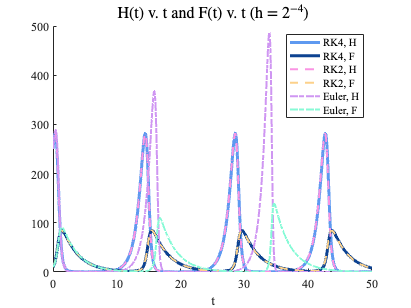

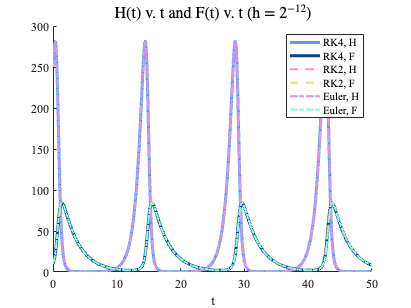

% Plot error at end value v. step size
n_min = 4;
n_max = 12;
base = 2;

% Number of step sizes to try
n_step = n_max - n_min + 1;

% Step sizes
h = zeros(1, n_step);

% Estimate at t = 50
w50_rk4 = zeros(2, n_step);
w50_rk2 = zeros(2, n_step);
w50_euler = zeros(2, n_step);


% Step size = 2^-n
for n = n_min : n_max
    i = n - n_min + 1; % index

    h(i) = base^-n;

    w_rk4 = rk4(f, t_start, t_end, h(i), x0);
    w50_rk4(:, i) = w_rk4(:, end);

    w_rk2 = rk2(f, t_start, t_end, h(i), x0);
    w50_rk2(:, i) = w_rk2(:, end);

    w_euler = euler(f, t_start, t_end, h(i), x0);
    w50_euler(:, i) = w_euler(:, end);

    % Graph the most accurate and least accurate solution for each method
    if n == n_min || n == n_max
        graph_lotka_volterra(w_rk4, w_rk2, w_euler, t_start, t_end, h(i))
        title(sprintf('H(t) v. t and F(t) v. t (h = $2^{-%d} )$', n), 'FontSize', 16, 'FontWeight', 'normal', 'Interpreter', 'latex')
    end
end

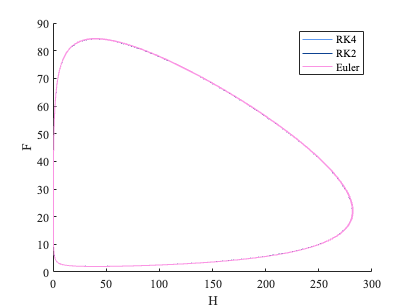

figure 
default_style()

hold on
plot(w_rk4(1, :), w_rk4(2, :))
plot(w_rk2(1, :), w_rk2(2, :))
plot(w_euler(1, :), w_euler(2, :))
hold off

xlabel('H')
ylabel('F')

legend('RK4', 'RK2', 'Euler')

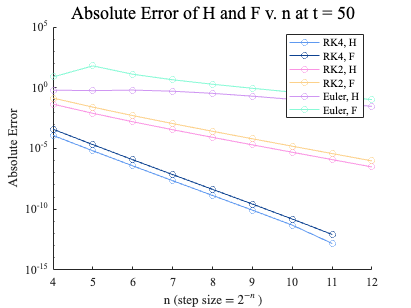

% Assume exact solution is best approximated by RK4, h = 2^-12
y50_H = w50_rk4(1, end);
y50_F = w50_rk4(2, end);

errors_rk4_H = abs(y50_H - w50_rk4(1, :));
errors_rk4_F = abs(y50_F - w50_rk4(2, :));

errors_rk2_H = abs(y50_H - w50_rk2(1, :));
errors_rk2_F = abs(y50_F - w50_rk2(2, :));

errors_euler_H = abs(y50_H - w50_euler(1, :));
errors_euler_F = abs(y50_F - w50_euler(2, :));

figure
default_style()

hold on
plot(n_min : n_max, errors_rk4_H, '-o')
plot(n_min : n_max, errors_rk4_F, '-o')

plot(n_min : n_max, errors_rk2_H, '-o')
plot(n_min : n_max, errors_rk2_F, '-o')

plot(n_min : n_max, errors_euler_H, '-o')
plot(n_min : n_max, errors_euler_F, '-o')

hold off

xlabel('n (step size = $2^{-n}$ )', 'Interpreter', 'latex')
ylabel('Absolute Error')
title('Absolute Error of H and F v. n at t = 50', 'FontSize', 18, 'FontWeight', 'normal')

set(gca, 'YScale', 'log')
legend('RK4, H', 'RK4, F', 'RK2, H', 'RK2, F',  'Euler, H', 'Euler, F')

## 2.

f = @(y, t) -7 * y;

% Analytical solution
y0 = 50;
y = @(t) y0 .* exp(-7 .* t);

t_start = 0;
t_end = 50;


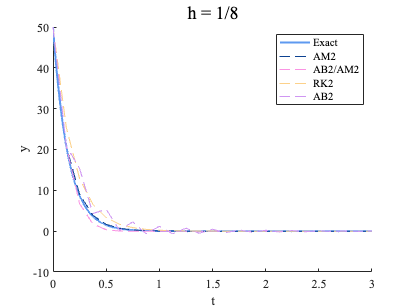

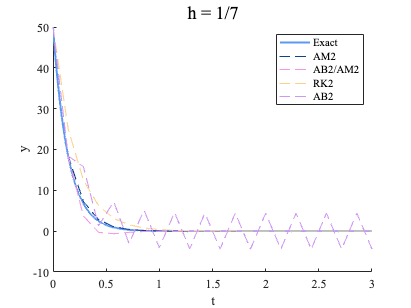

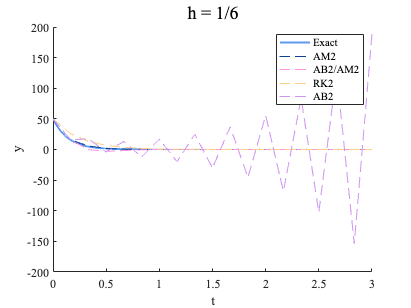

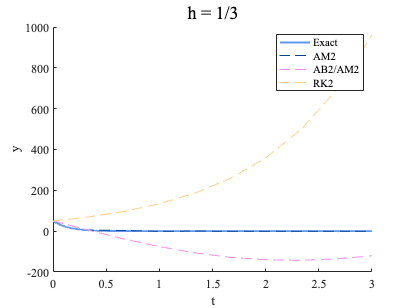

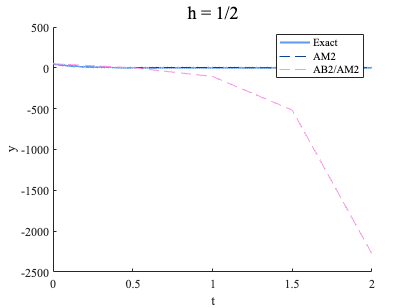

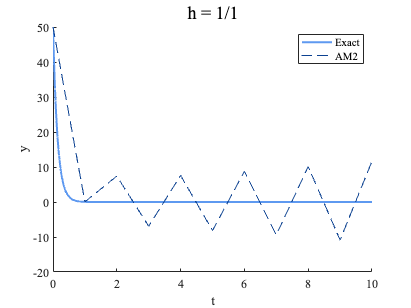

% h = 1/7 (AB2)
% h = 2/7 (RK2)
% h = 12/35 (AB2/AM2)
% h = 6/7 (AM2)

for h = [1/8, 1/7, 1/6, 1/3, 1/2, 1]
    w_rk2 = rk2(f, t_start, t_end, h, y0);
    w_ab2 = ab2(f, t_start, t_end, h, y0, y);
    w_am2 = am2(t_start, t_end, h, y0, y);
    w_adams2 = adams2(f, t_start, t_end, h, y0, y);

    figure
    default_style()
    hold on
    
    if h < 1/3
        plot(t_start:1e-3:t_end, y(t_start:1e-3:t_end), 'LineWidth', 2)
        plot(t_start:h:t_end, w_am2, '--')
        plot(t_start:h:t_end, w_adams2, '--')
        plot(t_start:h:t_end, w_rk2, '--')
        plot(t_start:h:t_end, w_ab2, '--')
    
        legend('Exact', 'AM2', 'AB2/AM2', 'RK2', 'AB2')
        xlim([0 3])

    elseif h < 1/2
        plot(t_start:1e-3:t_end, y(t_start:1e-3:t_end), 'LineWidth', 2)
        plot(t_start:h:t_end, w_am2, '--')
        plot(t_start:h:t_end, w_adams2, '--')
        plot(t_start:h:t_end, w_rk2, '--')
    
        legend('Exact', 'AM2', 'AB2/AM2', 'RK2')
        xlim([0 3])
    
    elseif h < 1
        plot(t_start:1e-3:t_end, y(t_start:1e-3:t_end), 'LineWidth', 2)
        plot(t_start:h:t_end, w_am2, '--')
        plot(t_start:h:t_end, w_adams2, '--')
    
        legend('Exact', 'AM2', 'AB2/AM2')
        xlim([0 2])
    
    elseif h < 2
        plot(t_start:1e-3:t_end, y(t_start:1e-3:t_end), 'LineWidth', 2)
        plot(t_start:h:t_end, w_am2, '--')
    
        legend('Exact', 'AM2')
        xlim([0 10])
    end
    
    hold off

    xlabel('t')
    ylabel('y')
    title(sprintf('h = 1/%d', 1/h), 'FontSize', 18, 'FontWeight', 'normal')
end

% 2-step Adams predictor-corrector stability condition: h < 12/35
h_unstable = 1/2;
h_stable_accurate = 1e-3;
h_stable_inaccurate = 1/3;

% Step size that violates the stability criterion
w_unstable = adams2(f, t_start, t_end, h_unstable, y0, y);

% Step size that satisfies the stability criterion
w_stable_accurate = adams2(f, t_start, t_end, h_stable_accurate, y0, y);

% Step size that satisfies the stability criterion but is not very accurate
w_stable_inaccurate = adams2(f, t_start, t_end, h_stable_inaccurate, y0, y);


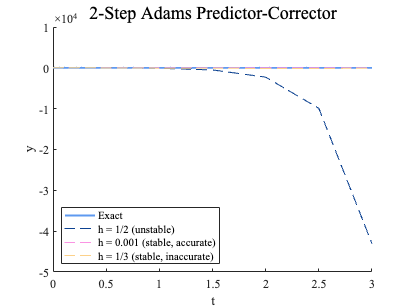

figure
default_style()

hold on
plot(t_start:1e-3:t_end, y(t_start:1e-3:t_end), 'LineWidth', 2)
plot(t_start:h_unstable:t_end, w_unstable, '--')
plot(t_start:h_stable_accurate:t_end, w_stable_accurate, '--')
plot(t_start:h_stable_inaccurate:t_end, w_stable_inaccurate, '--')
hold off

legend('Exact', 'h = 1/2 (unstable)', 'h = 0.001 (stable, accurate)', 'h = 1/3 (stable, inaccurate)', 'Location', 'southwest')

xlabel('t')
ylabel('y')
title('2-Step Adams Predictor-Corrector', 'FontSize', 18, 'FontWeight', 'normal')

xlim([0 3])

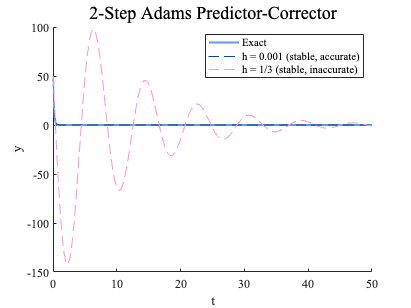

figure
default_style()

hold on
plot(t_start:1e-3:t_end, y(t_start:1e-3:t_end), 'LineWidth', 2)
plot(t_start:h_stable_accurate:t_end, w_stable_accurate, '--')
plot(t_start:h_stable_inaccurate:t_end, w_stable_inaccurate, '--')
hold off

legend('Exact', 'h = 0.001 (stable, accurate)', 'h = 1/3 (stable, inaccurate)')

xlabel('t')
ylabel('y')
title('2-Step Adams Predictor-Corrector', 'FontSize', 18, 'FontWeight', 'normal')

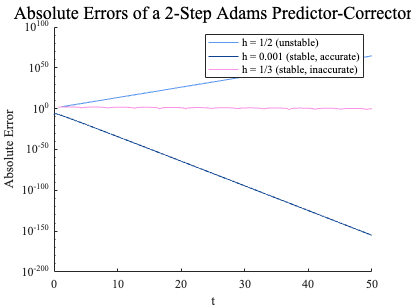

error_unstable = abs(w_unstable.' - y(t_start:h_unstable:t_end));
error_stable_accurate = abs(w_stable_accurate.' - y(t_start:h_stable_accurate:t_end));
error_stable_inaccurate = abs(w_stable_inaccurate.' - y(t_start:h_stable_inaccurate:t_end));

figure
default_style()

hold on
plot(t_start:h_unstable:t_end, error_unstable)
plot(t_start:h_stable_accurate:t_end, error_stable_accurate)
plot(t_start:h_stable_inaccurate:t_end, error_stable_inaccurate)
hold off

legend('h = 1/2 (unstable)', 'h = 0.001 (stable, accurate)', 'h = 1/3 (stable, inaccurate)')

xlabel('t')
ylabel('Absolute Error')
title('Absolute Errors of a 2-Step Adams Predictor-Corrector', 'FontSize', 18, 'FontWeight', 'normal')


set(gca, 'YScale', 'log')

## 3.

t_start = 0;
t_end = 100;

a_min = 0.5;
a_max = 5.5;

z0 = [0.0; 0.1];


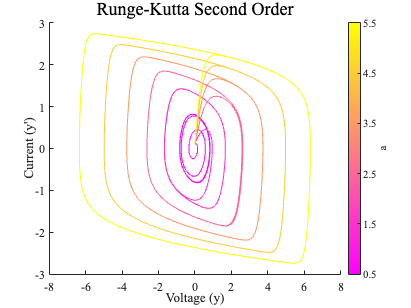

% Simple method to determine what the solution should look like
figure
default_style()

colormap spring
c = spring(length(a_min : a_max));
colororder(c);

hold on
for a = a_min : a_max
    
    % Decompose into a linear system: z1 = y, z2 = y'
    f = @(z, t) [z(2); 
                 a * z(2) - z(2)^3 - z(1)];

    % 4-step Adams predictor-corrector
    w = rk2(f, t_start, t_end, 1e-3, z0);

    plot(w(1, :), w(2, :))
end
hold off

% Labels
xlabel('Voltage (y)')
ylabel('Current (y'')')
title('Runge-Kutta Second Order', 'FontSize', 18, 'FontWeight', 'normal')

% Colorbar 
clim([a_min, a_max]);
cb = colorbar(); 
cb.Label.String = 'a';
cb.Ticks = a_min:1:a_max;

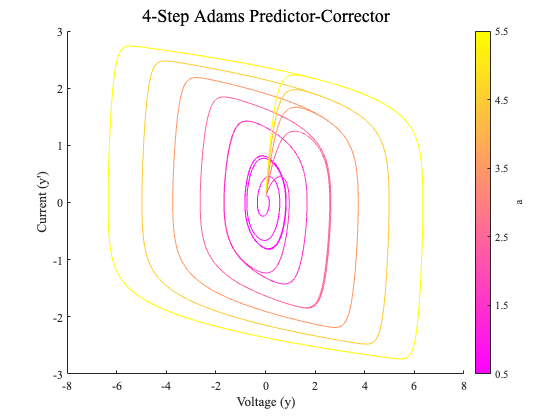

figure
default_style()

colormap spring
c = spring(length(a_min : a_max));
colororder(c);

hold on
for a = a_min : a_max
    
    % Decompose into a linear system: z1 = y, z2 = y'
    f = @(z, t) [z(2); 
                 a * z(2) - z(2)^3 - z(1)];

    % 4-step Adams predictor-corrector
    w = adams4(f, t_start, t_end, 1e-3, z0);

    plot(w(1, :), w(2, :))
end
hold off

% Labels
xlabel('Voltage (y)')
ylabel('Current (y'')')
title('4-Step Adams Predictor-Corrector', 'FontSize', 18, 'FontWeight', 'normal')

% Colorbar 
clim([a_min, a_max]);
cb = colorbar(); 
cb.Label.String = 'a';
cb.Ticks = a_min:1:a_max;

## Functions

function w = euler(f, a, b, h, y0)
    %{
        Uses Euler's method to approximate y(t) given f = dy/dt and h.
        
        Input:
            f: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
        
        Returns:
            w: approximated y values
    %}
   
    n = (b - a) / h;
    
    w = zeros(size(y0, 1), n + 1);
    w(:, 1) = y0;
    
    for i = 1 : n
        t = a + (i-1) * h;
        w(:, i+1) = w(:, i) + h .* f(w(:, i), t);
    end
end

function w = rk2(f, a, b, h, y0)
     %{
        Uses 2nd order Runga-Kutta to approximate y(t) given f = dy/dt and h.
        
        Input:
            f: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
        
        Returns:
            w: approximated y values
     %}

     n = (b - a) / h;

     w = zeros(size(y0, 1), n + 1);
     w(:, 1) = y0;

     for i = 1 : n
         t = a + (i-1) * h;

         w_mid = w(:, i) + h/2 .* f(w(:, i), t);
         t_mid = t + h/2;
   
         w(:, i+1) = w(:, i) + h .* f(w_mid, t_mid);
     end
end

function w = rk4(f, a, b, h, y0)
    %{
        Uses 4th order Runge-Kutta to approximate y(t) given f = dy/dt and h.
        
        Input:
            f: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
        
        Returns:
            w: approximated y values
    %}
    
    n = (b - a) / h;

    w = zeros(size(y0, 1), n + 1);
    w(:, 1) = y0;

    for i = 1 : n
        t = a + (i-1) * h;
        f1 = f(w(:, i), t);
        f2 = f(w(:, i) + h/2 .* f1, t + h/2);
        f3 = f(w(:, i) + h/2 .* f2, t + h/2);
        f4 = f(w(:, i) + h .* f3, t + h);
         
        w(:, i+1) = w(:, i) + h/6 .* (f1 + 2 .* (f2 + f3) + f4);
    end
end

function w = ab2(dy_dt, a, b, h, y0, y)
    %{
        2-step Adams-Bashforth.
        
        Input:
            f: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
            y: analytic solution
        
        Returns:
            w: approximated y values
    %}
    
    % Number of subintervals
    n = (b - a) / h;

    % Initial conditions
    w = zeros(n + 1, 1);
    f = zeros(n + 1, 1);

    w(1) = y0;
    f(1) = dy_dt(y0, a);
    
    % Compute the first step using the analytic solution
    w(2) = y(a + h);

    for i = 2 : n
        t = a + (i-1) * h;
        f(i) = dy_dt(w(i), t);
        
        w(i+1) = w(i) + h/2 * (3 * f(i) - f(i-1));
    end
end

function w = am2(a, b, h, y0, y)
    %{
        2-step Adams-Bashforth for y' = -7y.
        
        Input:
            f: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
            y: analytic solution
        
        Returns:
            w: approximated y values
    %}
    
    % Number of subintervals
    n = (b - a) / h;

    % Initial condition
    w = zeros(n + 1, 1);
    w(1) = y0;
    
    % Compute the first step using the analytic solution
    w(2) = y(a + h);

    for i = 2 : n
        % Specific to y' = -7y
        w(i+1) = 1/(1 + 35/12 * h) * ((1 - 56/12 * h) * w(i) + 7/12 * h * w(i-1));
    end
end

function w = adams2(dy_dt, a, b, h, y0, y)
    %{
        A 2-step Adams-Bashforth/Adams-Moulton predictor corrector
        with a single correction.
        
        Input:
            f: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
            y: analytic solution
        
        Returns:
            w: approximated y values
    %}
    
    % Number of subintervals
    n = (b - a) / h;

    % Initial conditions
    w = zeros(n + 1, 1);
    f = zeros(n + 1, 1);

    w(1) = y0;
    f(1) = dy_dt(y0, a);
    
    % Compute the first step using the analytic solution
    w(2) = y(a + h);

    for i = 2 : n
        t = a + (i-1) * h;
        f(i) = dy_dt(w(i), t);
        
        % Predict w(i+1) with the Adams-Bashforth 2-step predictor
        w(i+1) = w(i) + h/2 * (3 * f(i) - f(i-1));
        f(i+1) = dy_dt(w(i+1), t + h);
        
        % Correct w(i+1) with the Adams-Moulton 2-step corrector
        w(i+1) = w(i) + h/12 * (5 * f(i+1) + 8 * f(i) - f(i-1));
    end
end

function w = adams4(dy_dt, a, b, h, y0)
    %{
        A 4-step Adams-Bashforth/Adams-Moulton predictor corrector
        with a single correction.
        
        Input:
            f: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
        
        Returns:
            w: approximated y values
    %}
    
    % Number of subintervals
    n = (b - a) / h;

    % Initial conditions
    w = zeros(size(y0, 1), n + 1);
    f = zeros(size(y0, 1), n + 1);

    w(:, 1) = y0;
    f(:, 1) = dy_dt(y0, a);
    
    % Compute the first three (next) steps using RK4
    for i = 1:3
        f1 = dy_dt(y0, a);
        f2 = dy_dt(y0 + h/2 .* f1, a + h/2);
        f3 = dy_dt(y0 + h/2 .* f2, a + h/2);
        f4 = dy_dt(y0 + h .* f3, a + h);

        w(:, i+1) = y0 + h/6 .* (f1 + 2 .* (f2 + f3) + f4);

        a = a + h;
        y0 = w(:, i+1);
    end

    for i = 4 : n
        t = a + (i-1) * h;
        f(:, i) = dy_dt(w(:, i), t);
        
        % Predict w(i+1) with the Adams-Bashforth 4-step predictor
        w(:, i+1) = w(:, i) + h/24 .* (55 .* f(:, i)- 59 .* f(:, i-1) + 37 .* f(:, i-2) - 9 .* f(:, i-3));
        f(:, i+1) = dy_dt(w(:, i+1), t + h);
        
        % Correct w(i+1) with the Adams-Moulton 4-step corrector
        w(:, i+1) = w(:, i) + h/720 .* (251 .* f(:, i+1) + 646 .* f(:, i) - 264 .* f(:, i-1) + 106 .* f(:, i-2) - 19 .* f(:, i-3));
    end
end

function graph_lotka_volterra(w_rk4, w_rk2, w_euler, a, b, h)
    figure 
    default_style()

    hold on
    plot(a:h:b, w_rk4(1, :), 'LineWidth', 3)
    plot(a:h:b, w_rk4(2, :), 'LineWidth', 3)

    plot(a:h:b, w_rk2(1, :), '--', 'LineWidth', 2)
    plot(a:h:b, w_rk2(2, :), '--', 'LineWidth', 2)

    plot(a:h:b, w_euler(1, :), '-.', 'LineWidth', 2)
    plot(a:h:b, w_euler(2, :), '-.', 'LineWidth', 2)
    hold off

    xlabel('t')
    legend('RK4, H', 'RK4, F', 'RK2, H', 'RK2, F',  'Euler, H', 'Euler, F')
end

function default_style()
    color_order = [0.37 0.60 0.94
                   0.05 0.26 0.57
                   0.98 0.58 0.89
                   0.99 0.82 0.54
                   0.81 0.59 0.95
                   0.53 0.98 0.84];
    
    colororder(color_order)
    set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 12)
    set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 14)
end
